# Progsheet 1 - Introduction to the Numerics of partial differential equations

*Author: Sven Ullmann and Jonathan Schnitzler*

This is an exercise sheet in one space and one time dimension.

## Cars on a road

We consider the initial-boundary value-problem for a unknown $u\in C^1 \left(\Omega {\;}_{T\;} \right)$

        $\partial {\;}_t u\left(x,t\right)+\partial {\;}_x F\left\lbrack u\left(x,t\right)\right\rbrack =0$         in $\Omega {\;}_T$

                                    $u\left(\cdot ,0\right)=u_0$      in $\Omega \;$

        $\partial {\;}_x u\left(x_{\min } ,\cdot \;\right)=\partial {\;}_x u\left(x_{\max } ,\cdot \;\right)$           in $\left(0,T\right)$

We define 

%Domain
x_min = 0;
x_max = 5;
T = 1;


%Discretication
nt = 100;
dt = T/nt,

dt = 0.0100


nx = 100

nx = 100

dx = (x_max - x_min)/nx,

dx = 0.0500



omega = linspace(x_min, x_max, nx)

omega =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


omega_t = 0;


%Boundary values
u0 = initial_values(omega)

u0 =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


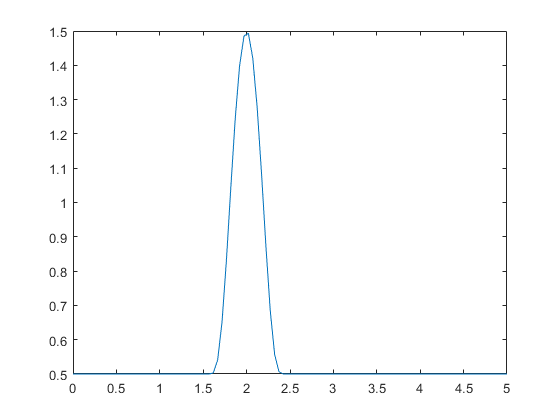

plot(omega, u0)


%Non Linear Function F
f = @(u) u.*(1-u)

f = function_handle with value:
    @(u)u.*(1-u)


### Flux kernels G

We will consider different flux kernels with which we will solve the iterative scheme for this PDE

#### Lax-Friedrichs

#### "Upwind"-Flux